clear
% 导入数据
opts = delimitedTextImportOptions("NumVariables", 5);

% 指定范围和分隔符
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% 指定列名称和类型
opts.VariableNames = ["time_stamp", "steering_wheel_angle", "speed", "yaw_rate", "Var5"];
opts.SelectedVariableNames = ["time_stamp", "steering_wheel_angle", "speed", "yaw_rate"];
opts.VariableTypes = ["double", "double", "double", "double", "string"];

% 指定文件级属性
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 指定变量属性
opts = setvaropts(opts, "Var5", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var5", "EmptyFieldRule", "auto");

% 导入数据
outputdata = readtable("D:\Programming\GITEE\position-analyze\matlab\output_data.csv", opts)

outputdata = 13707×4 table
    time_stamp    steering_wheel_angle    speed     yaw_rate 
    __________    ____________________    _____    __________

    3.1528e+09            -1.5              0               0
    3.1528e+09            -1.5              0      -0.0010908
    3.1528e+09            -1.5              0               0
    3.1528e+09            -1.5              0               0
    3.1528e+09            -1.5              0       0.0010908
    3.1529e+09            -1.5              0       0.0010908
    3.1529e+09            -1.5              0               0
    3.1529e+09            -1.5              0               0
    3.1529e+09            -1.5              0               0
    3.1529e+09            -1.5              0               0
     3.153e+09            -1.5              0               0
     3.153e+09            -1.5              0               0
     3.153e+09            -1.5              0               0
     3.153e+09            -1.5            


D = 1;                          % 维度，可取 1,2,3
N = length(outputdata.time_stamp)

N = 13707

 
A = eye(D);                     % 状态转移矩阵，和上一时刻状态没有换算，故取 D阶单位矩阵
yaw_rate_kf = zeros(D, N);                % 存储滤波后的数据
yaw_rate = ones(D, N);                 % 存储滤波前的数据

yaw_rate = outputdata.yaw_rate'

yaw_rate =          0   -0.0011         0         0    0.0011    0.0011         0         0         0         0         0         0         0         0         0         0         0         0    0.0011         0         0         0         0         0         0         0         0         0         0         0         0   -0.0011         0         0         0         0         0         0         0         0         0         0    0.0011    0.0011         0         0         0         0         0         0


t0 = outputdata.time_stamp'

t0 = 	1.0e+09 *

    3.1528    3.1528    3.1528    3.1528    3.1528    3.1529    3.1529    3.1529    3.1529    3.1529    3.1530    3.1530    3.1530    3.1530    3.1530    3.1531    3.1531    3.1531    3.1531    3.1531    3.1532    3.1532    3.1532    3.1532    3.1532    3.1533    3.1533    3.1533    3.1533    3.1533    3.1534    3.1534    3.1534    3.1534    3.1534    3.1535    3.1535    3.1535    3.1535    3.1535    3.1536    3.1536    3.1536    3.1536    3.1536    3.1537    3.1537    3.1537    3.1537    3.1537



K_k1(:, 1) = zeros(D,1);                        % 存卡尔曼增益
yaw_rate_kf(:, 1) = zeros(D,1);            % 初始值设为 1（可为任意数）
P_yaw_rate = eye(D);                     % 初始值为 1（可为非零任意数），取 D阶单位矩阵
Q = 1e-3*eye(D);                % 过程噪声协方差，估计一个

R_yaw_rate = [0.01];

% if D==1                         % 一维仅高度，气压计数据
%     true1D = t0*0.4;
% elseif D==2                     % 二维 x,y 方向，GPS数据
%     true2D = [r*cos(w*t0); r*sin(w*t0)];
% elseif D==3                     % 三维 x,y,z方向，GPS和气压计
%     true3D = [r * cos(w*t0); r * sin(w*t0); t0 * 0.4];
% end


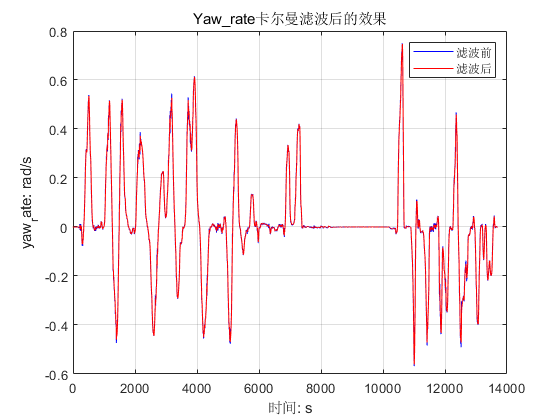


 
for k = 2:1:N        
    yaw_rate_kf(:,k) = A * yaw_rate_kf(:,k-1);      % 卡尔曼公式1
    P_yaw_rate = A * P_yaw_rate * A' + Q;         % 卡尔曼公式2
    H = eye(D);
    K = P_yaw_rate*H' * inv(H*P_yaw_rate*H' + R_yaw_rate); % 卡尔曼公式3

    yaw_rate_kf(:,k) = yaw_rate_kf(:,k) + K * (yaw_rate(:,k)-H*yaw_rate_kf(:,k));    % 卡尔曼公式4
    P_yaw_rate = (eye(D)-K*H) * P_yaw_rate;                       % 卡尔曼公式5
    
    K_k1(k-1) = K;
end
 
plot(yaw_rate,'b'); 
hold on;grid on;              % 坐标等距、继续绘图、添加网格
plot(yaw_rate_kf,'r');                           % 绘制滤波后数据
legend('滤波前','滤波后');           % 标注
title("Yaw\_rate卡尔曼滤波后的效果");
xlabel('时间: s');                         
ylabel('yaw_rate: rad/s');hold off;  

[pos_X,pos_Y] = get_pos(yaw_rate,outputdata.time_stamp,outputdata.speed);

temp_X = 0

temp_Y = 0

temp_PHI = 0

[pos_X_kf,pos_Y_kf] = get_pos(yaw_rate_kf,outputdata.time_stamp,outputdata.speed);

temp_X = 0

temp_Y = 0

temp_PHI = 0

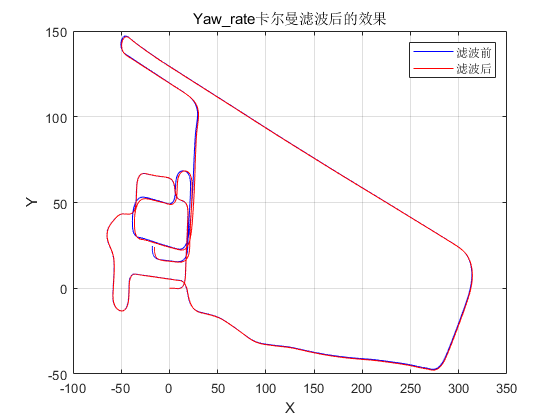

plot(pos_X,pos_Y,'b')
hold on;grid on;              % 坐标等距、继续绘图、添加网格
plot(pos_X_kf,pos_Y_kf,'r');                           % 绘制滤波后数据
legend('滤波前','滤波后');           % 标注
title("Yaw\_rate卡尔曼滤波后的效果");
xlabel('X');                         
ylabel('Y');hold off;  

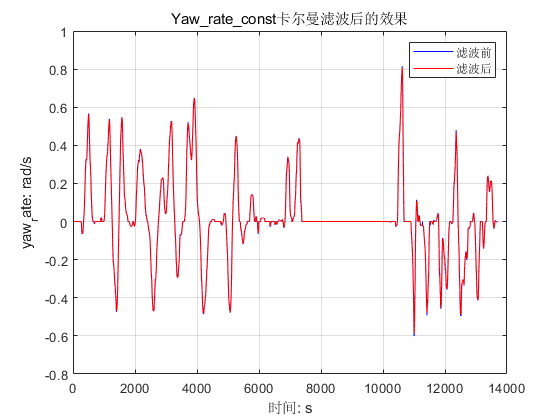

const_coef = 15;
wheel_base = 2.7;
A = eye(D);                     % 状态转移矩阵，和上一时刻状态没有换算，故取 D阶单位矩阵
yaw_rate_const_kf = zeros(D, N);                % 存储滤波后的数据
yaw_rate_const = ones(D, N);                 % 存储滤波前的数据

for i=1:1:N
    if(abs(outputdata.steering_wheel_angle(i))>5.0)
        yaw_rate_const(i)=outputdata.speed(i)*tan((outputdata.steering_wheel_angle(i)*pi)/(180*const_coef))/wheel_base;
    else
        yaw_rate_const(i)=0;
    end
end

yaw_rate_const_kf(:, 1) = zeros(D,1);            
K_k2(:, 1) = zeros(D,1);                        % 存卡尔曼增益
P_yaw_rate_const = eye(D);                     % 初始值为 1（可为非零任意数），取 D阶单位矩阵
R_yaw_rate_const = [0.02];

for k = 2:N        
    yaw_rate_const_kf(:,k) = A * yaw_rate_const_kf(:,k-1);      % 卡尔曼公式1
    P_yaw_rate_const = A * P_yaw_rate_const * A' + Q;         % 卡尔曼公式2
    H = eye(D);
    K = P_yaw_rate_const*H' * inv(H*P_yaw_rate_const*H' + R_yaw_rate_const); % 卡尔曼公式3

    yaw_rate_const_kf(:,k) = yaw_rate_const_kf(:,k) + K * (yaw_rate_const(:,k)-H*yaw_rate_const_kf(:,k));    % 卡尔曼公式4
    P_yaw_rate_const = (eye(D)-K*H) * P_yaw_rate_const;                       % 卡尔曼公式5
    
    K_k2(k-1) = K;
end
 
plot(yaw_rate_const,'b'); 
hold on;grid on;              % 坐标等距、继续绘图、添加网格
plot(yaw_rate_const_kf,'r');                           % 绘制滤波后数据
legend('滤波前','滤波后');           % 标注
title("Yaw\_rate\_const卡尔曼滤波后的效果");
xlabel('时间: s');                         
ylabel('yaw_rate: rad/s');hold off;  

[pos_X_const,pos_Y_const] = get_pos(yaw_rate_const,outputdata.time_stamp,outputdata.speed);

temp_X = 0

temp_Y = 0

temp_PHI = 0

[pos_X_const_kf,pos_Y_const_kf] = get_pos(yaw_rate_const_kf,outputdata.time_stamp,outputdata.speed);

temp_X = 0

temp_Y = 0

temp_PHI = 0

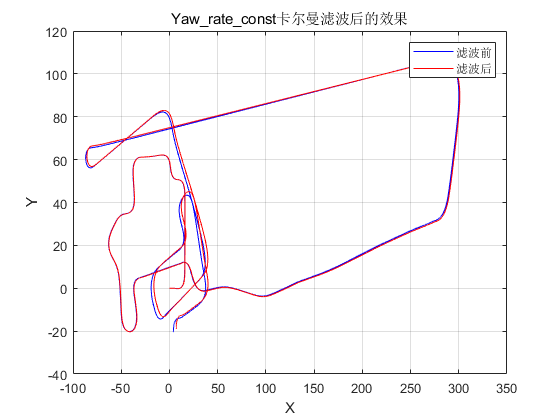

plot(pos_X_const,pos_Y_const,'b')
hold on;grid on;              % 坐标等距、继续绘图、添加网格
plot(pos_X_const_kf,pos_Y_const_kf,'r');                           % 绘制滤波后数据
legend('滤波前','滤波后');           % 标注
title("Yaw\_rate\_const卡尔曼滤波后的效果");
xlabel('X');                         
ylabel('Y');hold off;  

P_cov = eye(2); %   两路卡尔曼间的协方差
A_hat = zeros(2,1);
A_hat_data = zeros(2,N-1);
e = ones(2,1);
for i=1:N-1
    P_cov(1,1) = (1-K_k1(i))*(P_cov(1,1)+Q)*(1-K_k1(i));
    P_cov(1,2) = (1-K_k1(i))*(P_cov(1,2)+Q)*(1-K_k2(i));
    P_cov(2,1) = (1-K_k2(i))*(P_cov(2,1)+Q)*(1-K_k1(i));
    P_cov(2,2) = (1-K_k2(i))*(P_cov(2,2)+Q)*(1-K_k2(i));
    A_hat = inv(P_cov)*e*inv(e'*inv(P_cov)*e);
    A_hat_data(:,i) = A_hat;
    
end